# ROS Services

**Service Overview**

- *Services *are a distinct communication method based on a "client-server" architecture.

- Clients **request** the server to process the input data and produce a **response** by making a **call.**

**Service Topics**

- Services use **service topics **and **service messages types.**

- It is the **service topic name **that identifies a service.

**Service Messages**

- Service topics are associated with a **parent message type**.

- Note that each message type has 2 sub-types: one for **requests** and another for **responses**. 

**Example**:

- Parent message name:roscpp_tutorials/TwoInts

-     Request sub-type: roscpp_tutorials/TwoIntsRequest

-     Response sub-type: roscpp_tutorials/TwoIntsResponse

- Service message types cannot be created directly in matlab, rather in native ROS. 

-     For now, we will use already existing service topics.

In this notebook we start with two toy service examples:

- Add 2 numbers

- Simple received message to swtich behavior

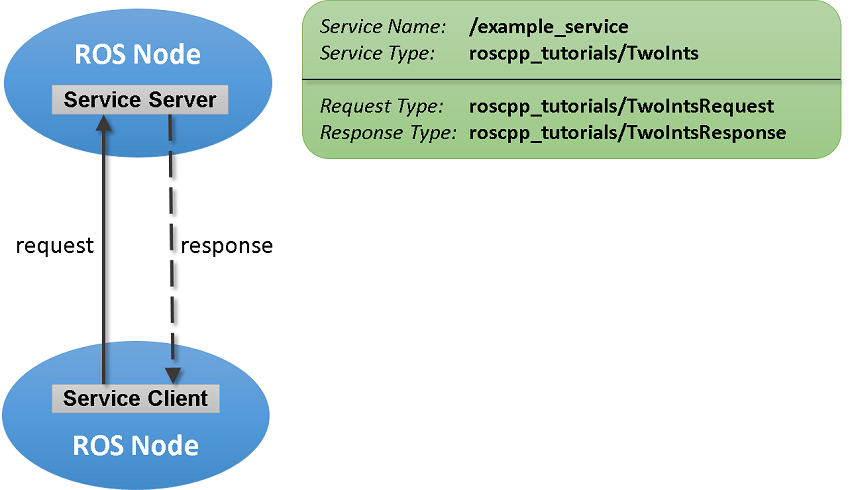

## Command Line Helper Tools

Close any communications in case they are running:

clear
rosshutdown

Start the network.

rosinit

Below is an example of launch two services, but we will run through this manually.

%ex_service_net

### List Services

We are looking for our two toy services:

- /add 

- /reply. 

The rest of the services (processes) are created by defaul for logging.

rosservice list

Launching ROS Core...
.Done in 1.19 seconds.
Initializing ROS master on http://192.168.56.1:11311.
Initializing global node /matlab_global_node_80098 with NodeURI http://notthefav:65290/ and MasterURI http://localhost:11311.


### Service Types

In MATLAB, we can retrieve a list of existing messages. Some of which are service type messages (others are regular topic messages and others are action messages, which we will look at later).

rosmsg list

We can also do it programmatically:

services = rosmsg('list')

But what are the types for the messages above, for example the '/add' topic?

It is the equivalent 

We can use the the `rosservice info /topic_name to identify it:`

rosservice info /add

We see the type is roscpp_tutorials/TwoInts. However, this is a parent type. 

Remember that ros services have both responses and requests sub-versions. 

We can study the format of these types using 

- rosmsg show typeRequest (i.e. inputs to the service server)

- rosmsg show typeResponse (i.e. the output)

#### **The Inputs to /add**

Let's understand the data structure for the service request (i.e. the inputs to the service).

rosmsg show roscpp_tutorials/TwoIntsRequest

ackermann_msgs/AckermannDrive                                  
ackermann_msgs/AckermannDriveStamped                           
actionlib/TestAction                                           
actionlib/TestActionFeedback                                   
actionlib/TestActionGoal                                       
actionlib/TestActionResult                                     
actionlib/TestFeedback                                         
actionlib/TestGoal                                             
actionlib/TestRequestAction                                    
actionlib/TestRequestActionFeedback                            
actionlib/TestRequestActionGoal                                
actionlib/TestRequestActionResult                              
actionlib/TestRequestFeedback                                  
actionlib/TestRequestGoal                                      
actionlib/TestRequestResult                                    
actionlib/TestResult                    

Notice that the function output indicates that this message has two ints: 

- int64 A

- int64 B

**Note:**

- The type int64 is not the same thing as int. The regular int has two 32 bits vs 64. 

- Later when we populate the message, take care in casting regular values as int64.

#### The Output of /add

Let's also understand the data structure for the service response (i.e. the output):

rosmsg show roscpp_tutorials/TwoIntsResponse

services = 2770×1 cell array
    {'ackermann_msgs/AckermannDrive'              }
    {'ackermann_msgs/AckermannDriveStamped'       }
    {'actionlib/TestAction'                       }
    {'actionlib/TestActionFeedback'               }
    {'actionlib/TestActionGoal'                   }
    {'actionlib/TestActionResult'                 }
    {'actionlib/TestFeedback'                     }
    {'actionlib/TestGoal'                         }
    {'actionlib/TestRequestAction'                }
    {'actionlib/TestRequestActionFeedback'        }
    {'actionlib/TestRequestActionGoal'            }
    {'actionlib/TestRequestActionResult'          }
    {'actionlib/TestRequestFeedback'              }
    {'actionlib/TestRequestGoal'                  }
    {'actionlib/TestRequestResult'                }
    {'actionlib/TestResult'                       }
    {'actionlib/TwoIntsAction'                    }
    {'actionlib/TwoIntsActionFeedback'            }
    {'actionlib/TwoIntsActionGoal' 

Notice the function output shows that the ***response*** will be encoded in a variable called Sum, which should encode the sum of A & B.

% Case matters

## Service for Adding Two Numbers

### **01 The Service Callback Function**

In a moment we will create a service server. The job of the service server is to:

- Receive the request

- Use a callback to process the request and produce a response

- Return the response

As such, one must create a callback function that takes a request and a response and handles them. 

We will create a callback called: `sumtwoints(). Open the script below to analyze it.`

sumtwoints

### 02 Creating the Service Server "/add"

Once we have our service callback, we can create the service server using rossvcserver.

rossvcserver will request the following:

- service topic name

- service message type (parent type)

- callback handle

- Dataformat information

add_service = rossvcserver('/add', ...                     % Service topic

Node: /matlab_global_node_80098
URI: rosrpc://notthefav:65289
Type: roscpp_tutorials/TwoInts
Args: MessageType A B


                           'roscpp_tutorials/TwoInts',...  % Service message
                           @sumtwoints,...                  %callback
                           'DataFormat','struct'); 

### 03 Create the Service Client

To call the service server, you have to create a service client. Note that this client can be created anywhere in the ROS network. For the purposes of this example, we will create a client for the `/sum` service in MATLAB.

add_client = rossvcclient("/add","DataFormat","struct")

int64 A
int64 B



### 04 Create the Service Message

As with regular topic messages, the best way to instantiate a message is to simply call [**rosmessage**](https://www.mathworks.com/help/ros/ref/rosmessage.html)**() **with the object that captures the type, in this case the request object **add_client**.

add_request = rosmessage(add_client)


int64 Sum



#### Populating the Service Message

After creating the service message, we need to populate it. Specfiically, the request fields.

Now populate the service message:

add_request.A = int64(2);

Not enough input arguments.

Error in sumtwoints (line 17)
    response.Sum = request.A + request.B;  % Perform the addition

add_request.B = int64(1)

### 05 Calling the Service and Getting a Response

Once the service request message is populated, we can use the [**call**](https://www.mathworks.com/help/ros/ref/serviceclient.call.html)**()** method to call the service server, with our message. 

The [**call**](https://www.mathworks.com/help/ros/ref/serviceclient.call.html)**() **method takes the following arguments:

- client object

- service message

- 'Timeout' - optional

- Timeout Value optional

Let's make a simple call:

call(add_client, add_request)

#### **Checking for Service Server Availability**

Network problems may sometimes arise. You may think that your service server is running or available, but it may not be. 

In those cases, your code may crash if you use call directly.

Intead it is best to check for the availability of the servier through the [**isServerAvailable**](https://www.mathworks.com/help/ros/ref/serviceclient.isserveravailable.html)**() **method.

The isServerAvailable() method takes in 1 argument as the client (not the server!)

if isServerAvailable(add_client)
    sumresp = call(add_client,add_request,"Timeout",3)
else
    error("Service server not available on network")
end

## Summary

Let's recap. There are five steps to get a service going:

- Create or use an existing service callback

- Insantiated a Service Server

- Instanitate a Service client

- Instantiate and populate the Service Message

- Call the service server with client object and message

## Create Trigger Services

We are repeating the same thing with a simpler service type. 

Sometimes, we may desire to have ***trigger-based operations*** like ***resets  or*** ***boolean operations.***

Calling the service executes a predefined action in the callback without requiring input parameters or returning any meaningful data.

### 01 Define the Service Callback

Use a service callback for trigger mechanism, open the following script to study it.

trigger_service_callback

add_client =   ServiceClient with properties:

     ServiceType: 'roscpp_tutorials/TwoInts'
     ServiceName: '/add'
    IsPersistent: 1
      DataFormat: 'struct'


### 02 Instantiate the Service Server

This service server will use a service topic "**/reply**" and an empty service message "**std_srvs/Empty**"

- To do: student, study the std_srvs/Empty using the [rosservce](https://www.mathworks.com/help/ros/ref/rosservice.html) helper function.

Create the server below:

test_server = rossvcserver("/reply", ...
                          "std_srvs/Empty", ...
                          @trigger_service_callback, ...
                          "DataFormat","struct")

Can you see the new service?

rosservice list

add_request = struct with fields:
    MessageType: 'roscpp_tutorials/TwoIntsRequest'
              A: 0
              B: 0


Can you verify the type of the service message?

rosservice info /reply

### 03 Insantiate the Service Client

Create a service client for the `/reply ` service that we just created.

test_client = rossvcclient("/reply","DataFormat","struct")

### 04 Instanitate the Service Message

Create an empty request message for the service. 

test_req = rosmessage(test_client)

add_request = struct with fields:
    MessageType: 'roscpp_tutorials/TwoIntsRequest'
              A: 2
              B: 1


In this case, we do not need to populate the message, since it is an empty trigger-based message:

### 05 Call the Service

Ensure that the service is connected to the client, waiting for them to connect if necessary.

if isServerAvailable(test_client)
    sumresp = call(test_client,test_req,"Timeout",3)
else
    error("Service server not available on network")
end

Below is an even more sophisticated way of checking errors. This will be left for yout to study on your own:

If the call function above fails, it will error. Instead of an error, if you would prefer to react to a call failure using conditionals; in addition to the response return the `status` and `statustext` outputs from the call function. 

- `response: r`esponse message sent by the service server, returned as a `Message` object handle or structure.

- `status: `indicates if the call succeeded

- `statustext: `provides additional information

% Counter
numCallFailures = 0;

ans = struct with fields:
    MessageType: 'roscpp_tutorials/TwoIntsResponse'
            Sum: 18



% Call your server, but this time collect more info on the output side for introspection.
[testresp,status,statustext] = call(test_client,test_req,"Timeout",3);

% 
if ~status
    numCallFailures = numCallFailues + 1;
    fprintf("Call failure number %d. Error cause: %s\n",numCallFailures,statustext)
else
    disp(testresp)
end

sumresp = struct with fields:
    MessageType: 'roscpp_tutorials/TwoIntsResponse'
            Sum: 18


## Shut Down ROS Network

Remove the sample nodes and service servers from the ROS network.

clear
rosshutdown

## Interacting with Gazebo

### Start Gazebo

It is time to begin interacting with the Gazebo simulation for the first time.

- Open  your virtual machine

- Start gazebo by opening a terminal and running: 

                    >> cd src/arm_gazebo/docker

                    >> ./run.bash

### Connect to the VM ROS Master

We will need to connect to the ROS master found inside the virtual machine:

rosinit("192.168.56.101", 11311, "NodeHost","192.168.56.1");

trigger_service_activated
Reset operation initiated...
Reset operation succesfully completed.


**List Gazebo Services**

Recall, we can list all services with:

rosservice list

Try to identify those that belong to Gazebo...

### Reset the Simulation

We can see that there is a service that reset the simulation. We can trigger it by doing three things:

- Check service message type for service topic (empty message)

- Insantiate a client of that service type

- Instanitate a message (no need to populate it)

- Call the service

Check the type

rosservice type '/gazebo/reset_world'

test_server =   ServiceServer with properties:

      ServiceType: 'std_srvs/Empty'
      ServiceName: '/reply'
    NewRequestFcn: @trigger_service_callback
       DataFormat: 'struct'


Insantiate the client:

res_client = rossvcclient('/gazebo/reset_world','DataFormat','struct');

Instantiate the message:

res_req = rosmessage(res_client);

/add
/matlab_global_node_80098/get_loggers
/matlab_global_node_80098/set_logger_level
/reply


Call the service:

call(res_client, res_req)

## Getting Gazebo Object Names

Now, let us pull the names of all objects in the simulation:

model_client = rossvcclient('/gazebo/get_world_properties', 'DataFormat','struct');

Node: /matlab_global_node_80098
URI: rosrpc://notthefav:65289
Type: std_srvs/Empty
Args: MessageType


modle_req = rosmessage(model_client);
resp=call(model_client,modle_req);
rosShowDetails(resp)

test_client =   ServiceClient with properties:

     ServiceType: 'std_srvs/Empty'
     ServiceName: '/reply'
    IsPersistent: 1
      DataFormat: 'struct'


test_req = struct with fields:
    MessageType: 'std_srvs/EmptyRequest'


sumresp = struct with fields:
    MessageType: 'std_srvs/EmptyResponse'


std_srvs/Empty


ans = struct with fields:
    MessageType: 'std_srvs/EmptyResponse'


ans =     '
       MessageType      :  gazebo_msgs/GetWorldPropertiesResponse
       SimTime          :  97.22799999999999
       ModelNames       :  {1}  ground_plane   {2}  table1   {3}  table2   {4}  unit_box   {5}  BlueBin   {6}  GreenBin   {7}  robot   {8}  wcase   {9}  box1   {10}  box2   {11}  scale1   {12}  block1   {13}  block2   {14}  block3   {15}  block4   {16}  block5   {17}  block6   {18}  block7   {19}  block8   {20}  block9   {21}  block10   {22}  block11   {23}  block12   {24}  gCan1   {25}  gCan2   {26}  gCan3   {27}  gCan4   {28}  rCan1   {29}  rCan2   {30}  rCan3   {31}  yCan1   {32}  yCan2   {33}  yCan3   {34}  yCan4   {35}  rBottle1   {36}  rBottle2   {37}  bBottle1   {38}  bBottle2   {39}  bBottle3   {40}  yBottle1   {41}  yBottle2   {42}  yBottle3   {43}  yBottle4   {44}  marker1   {45}  marker2   {46}  marker3   {47}  spam1   {48}  spam2   {49}  spam3   
       RenderingEnabled :  1
       Success          :  1
       StatusMessage    :  GetWorldProperties: got

HW:

Can you figure out how to get the pose of each object wrt to the world frame in Gazebo using the get_model_state service?

rosservice type '/gazebo/get_model_state'